data = importdata("Assignment_Data_SC42145_2022.mat")

data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]



A=data.A

A =    -0.4220   -0.2204         0   -0.2204         0
    0.0233   -0.0109   -0.0400   -0.0096         0
         0    1.0000         0         0         0
    0.1455   -0.0598         0   -0.1651  -10.8232
         0         0         0    1.0000         0


B=data.B

B =    -0.0799   -0.0096    0.2204
   -0.0067         0    0.0096
         0         0         0
   -0.0420         0    0.0598
         0         0         0


C=data.C

C =      1     0     0     0     0
     0     0     1     0     1


D=data.D

D =      0     0     0
     0     0     0


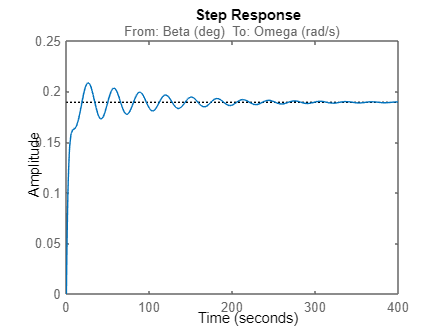

%print(data)
sys1 = ss(A,B,C,D);


step(-FWT(1,1))

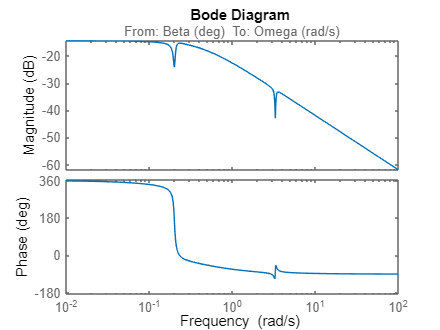

bode(-FWT(1,1))

margin(-FWT(1,1))
pzplot(-FWT(1,1))
stepinfo(-FWT(1,1))


% PID controller
Plant = -FWT(1,1);
Kp = 29.5;
Ki = 26.2;
Kd = 4.3;
Tf = 0.06;
% C = pid(Kp,Ki,Kd,Tf)

C = pidtune(Plant,'PID');
fbsys = feedback(Plant,C)

fbsys =
 
  A = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s       -0.4935       -0.2204             0       -0.2204             0
   z1dot (m/s)        0.01726      -0.01085         -0.04     -0.009574             0
   z1 (m)                   0             1             0             0             0
   z2dot (m/s)         0.1079      -0.05984             0       -0.1651        -10.82
   z2 (m)                   0             0             0             1             0
   ?                       -1             0             0             0             0
   ?                        0             0             0             0             0
   ?                        1             0             0             0             0
 
                            ?             ?             ?
   Omega (rad/s        0.0565       0.02263             0
   z1dot (m/s)       0.004755      0.001904             0
   z1 (m)                   0    

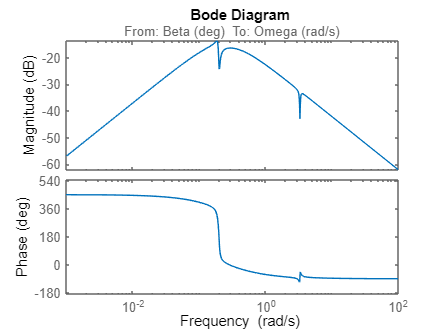

bode(fbsys)

stepinfo(fbsys)

ans = struct with fields:
         RiseTime: 0
    TransientTime: 281.4714
     SettlingTime: NaN
      SettlingMin: -0.0173
      SettlingMax: 0.1142
        Overshoot: Inf
       Undershoot: Inf
             Peak: 0.1142
         PeakTime: 3.8791
